tone2frequency(5,"D",2,0)

ans = 1.7592e+03

y = gen_wave(1,"C",1,0,1, 8192,"null")

y =                    0   0.762688161006988   0.761628228180223   0.844014940871963   0.997766478213723   0.809891778948462   0.612544042184343   0.323509245213436  -0.086058537438635  -0.403628698098075  -0.702088143638192  -0.893709079173446  -0.942954106282582  -0.856533138435868  -0.683944628604667  -0.736164562406600   0.479802640774720   0.692117206334855   0.840427467650457   0.871869029130500   0.974072629158304   0.754887395705910   0.499090483108226   0.225529035914807  -0.230957662386615  -0.504160348807550  -0.757037584363141  -0.976878477481245  -0.869286707528293  -0.838109057121455  -0.694728239037899  -0.461699052036730   0.742086353275762   0.685952665237240   0.856066927760961   0.946477839871534   0.889480802282075   0.698911822813814   0.399726562065213   0.078484909134780  -0.327144728636565  -0.617375281479254  -0.813027145451497  -0.996782567048024  -0.844126607801418  -0.757300864846049  -0.765082050042364   0.023694054850415   0.760094989819633   0.76595202652

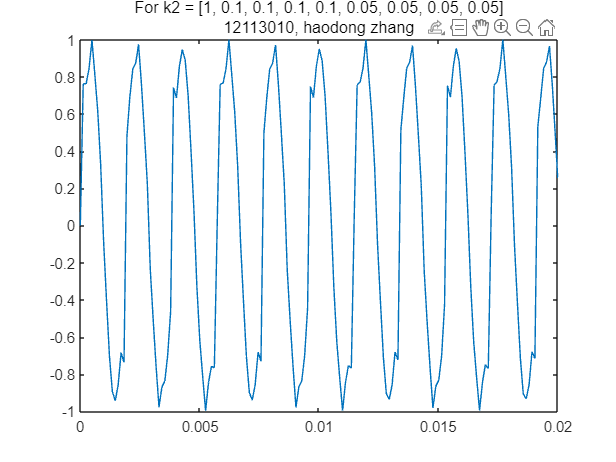

sound(y,8192);
t = linspace(0,1,8192);
plot(t,y);
xlim([0,0.02]); 
title(sprintf('For k2 = [1, 0.1, 0.1, 0.1, 0.1, 0.05, 0.05, 0.05, 0.05]\n12113010, haodong zhang'))

sound(y)

e指数衰减

out1 = y.*exp(-t/1)

out1 =                    0   0.390461806261070   0.718829660056801   0.932979548754413   0.998936035369454   0.906262543297638   0.669712758538398   0.326881847929010  -0.067768583821966  -0.451562178840278  -0.763561760198756  -0.954244683823260  -0.993363396590113  -0.874743522135148  -0.617258368475321  -0.261826055869923   0.135092959546351   0.510464630458776   0.804691646747435   0.971075625126901   0.983228860763543   0.839259282677366   0.562064901719682   0.195691947678676  -0.201664078230336  -0.566902303299270  -0.842037015146025  -0.983403547556893  -0.968587982769217  -0.799980908265300  -0.504391776774294  -0.128786064253460   0.267176961511667   0.620620206476943   0.875433337953745   0.991180489160937   0.949516953218758   0.757096614003998   0.444509320563637   0.061417901021224  -0.331332097578773  -0.671376366686860  -0.904734587527396  -0.994379531213642  -0.926112207456259  -0.710810846915868  -0.382697502744589   0.006101522535155   0.393836809252416   0.71894291

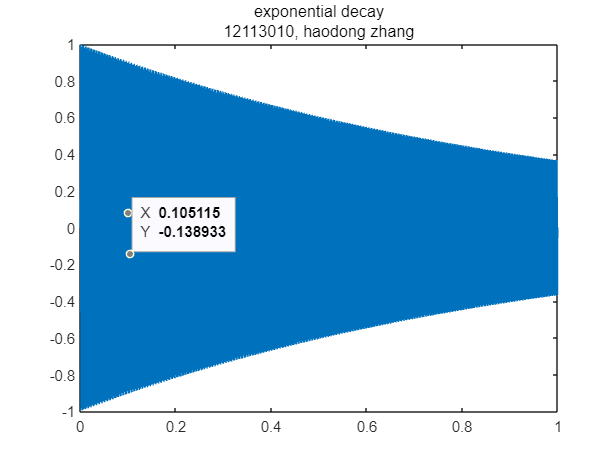

plot(t,out1);
title(sprintf('exponential decay\n12113010, haodong zhang'))

sound(out1)

0.5指数衰减

out2 = y.*0.5.^(t/1)

out2 =          0    0.3905    0.7189    0.9331    0.9991    0.9064    0.6699    0.3270   -0.0678   -0.4517   -0.7638   -0.9546   -0.9938   -0.8752   -0.6176   -0.2620    0.1352    0.5108    0.8052    0.9718    0.9840    0.8399    0.5625    0.1959   -0.2018   -0.5674   -0.8429   -0.9844   -0.9696   -0.8009   -0.5050   -0.1289    0.2675    0.6214    0.8765    0.9925    0.9508    0.7581    0.4451    0.0615   -0.3318   -0.6724   -0.9062   -0.9960   -0.9276   -0.7120   -0.3834    0.0061    0.3945    0.7203


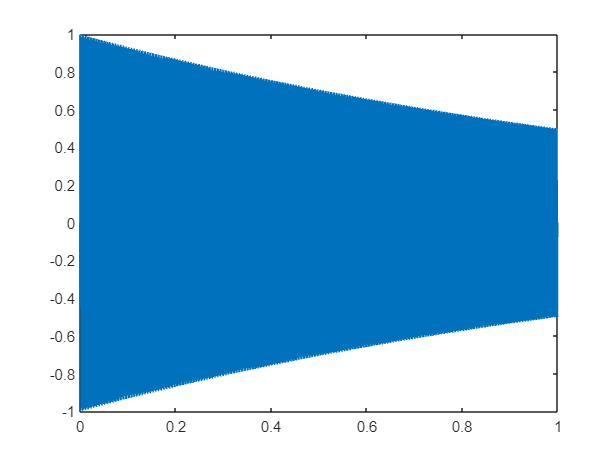

plot(t,out2);

线性衰减

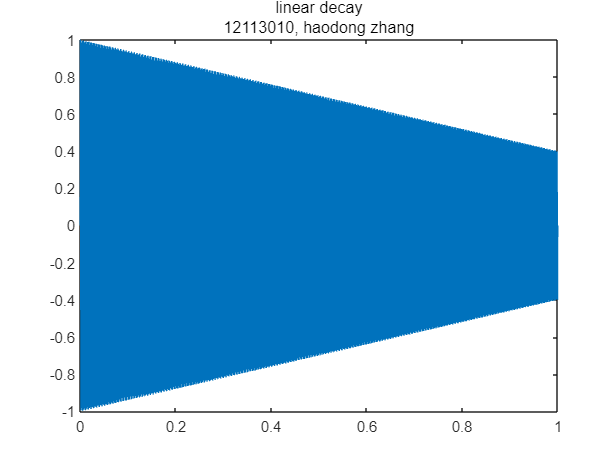

out3 = y.*(1+(0.4-1)/1*t);
plot(t,out3);
title(sprintf('linear decay\n12113010, haodong zhang'))

sound(out3)

平方衰减

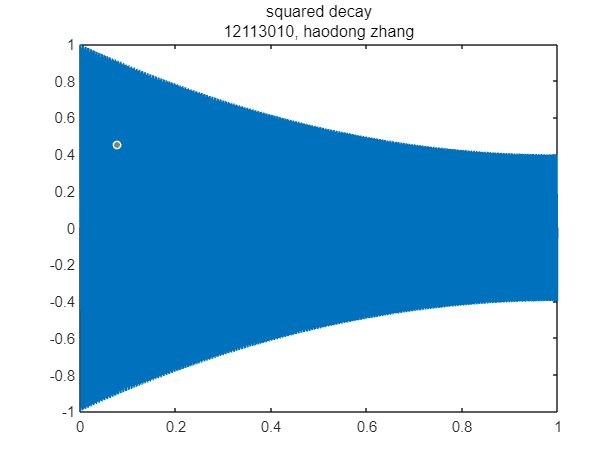

out4 = y.*(0.6*t.^2-1.2*t+1);
plot(t,out4);
title(sprintf('squared decay\n12113010, haodong zhang'))

sound(out4)

toneMatrix =   [6   7   1   7   1   3   7   3   3   6   5   6   1   5   0   3   3  ... 
    4   3   4   1   3   0   1   1   1   7   4   4   7   7   0   6   7   1   7   1  ... 
    3   7   0   3   3   6   5   6   1   5   0   3   4   1   7   7   1   2   2   3  ... 
    1   0   1   7   6   6   7   5   6   0   1   2   3   2   3   5   2   0   5   5  ...
    1   7   1   3   3   0   0   6   7   1   7   2   2   1   5   5   0   4   3   2  ...
    1   3   3   0   3   6   5   5   3   2   1   0   1   2   1   2   2   5   3   0  ...
    3   6   5   3   2   1   0   1   2   1   2   2   7   6   0   6   7   6];
noctaveMatrix =[0   0   1   0   1   1   0   0   0   0   0   0   1   0   0   0   0  ...
    0   0   0   1   0   0   1   1   1   0   0   0   0   0   0   0   0   1   0   1  ...
    1   0   0   0   0   0   0   0   1   0   0   0   0   1   0   0   1   1   1   1  ...
    1   0   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0  ...
    1   0   1   1   1   0   0   0   0   1   0   1   1   1   0   0   0   1   1   1  ...
    1   1   1   0   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0  ...
    1   1   1   1   1   1   0   1   1   1   1   1   0   0   0   0   0   0];
risingMatrix = [0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  ...
    0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0];
rhythmMatrix = 1.5*[1/8 1/8 3/8 1/8 1/4 1/4 3/4 1/8 1/8 3/8 1/8 1/4 1/4 2/4 1/4 1/8 ...
    1/8 3/8 1/8 1/8 3/8 2/4 1/8 1/8 1/8 1/8 3/8 1/8 1/4 1/4 2/4 1/4 1/8 1/8 3/8 1/8 ...
    1/4 1/4 2/4 1/4 1/8 1/8 3/8 1/8 1/4 1/4 3/4 1/8 1/8 1/4 1/8 1/8 1/4 1/4 1/8 1/8 ...
    1/8 1/4 1/4 1/4 1/8 1/8 1/8 1/4 1/4 2/4 1/4 1/8 1/8 3/8 1/8 1/4 1/4 2/4 1/4 1/8 ...
    1/8 1/8 1/8 1/4 1/4 2/4 1/4 1/4 1/8 1/8 1/4 1/4 1/8 1/8 3/8 1/8 1/4 1/4 1/4 1/4 ...
    1/4 1/4 4/4 2/4 1/4 1/4 2/4 1/4 1/4 1/8 1/8 1/4 1/8 1/8 1/4 1/8 1/8 1/8 1/4 2/4 ...
    1/4 1/4 2/4 2/4 1/8 1/8 2/4 1/8 1/8 1/4 1/8 1/8 1/8 1/4 2/4 1/4 1/8 1/8 4/4];
music = gen_music(toneMatrix,"D",noctaveMatrix,risingMatrix,rhythmMatrix,8192,"exp_pro")

music =                    0   0.364120522279377   0.295799728363480   0.322194837496424   0.296322914699108   0.220333149117629   0.197454382981504   0.141221994843319   0.005168915935451  -0.040757772915162  -0.193971702289403  -0.190903266017996  -0.259538734306644  -0.317235950474596  -0.312179608647723  -0.332163647680381  -0.296264174359000   0.229132233862147   0.351185637559382   0.305243740948643   0.323298192138322   0.273853729171257   0.195148541964590   0.203109985275364   0.066977988609622  -0.001180289495923  -0.111955212939409  -0.203573805660273  -0.208945200603680  -0.290687472575597  -0.327746029603996  -0.299314248957193  -0.372393680252115  -0.099693131438942   0.357661707579357   0.309891543724581   0.323086132526640   0.308047255379110   0.237969623730815   0.194310229487490   0.168530043003954   0.014539574944084  -0.021334746414294  -0.178755070916707  -0.192572781322260  -0.245271429532307  -0.311373087810013  -0.320050137300847  -0.315901468180304  -0.3429072

sound(music,8192)

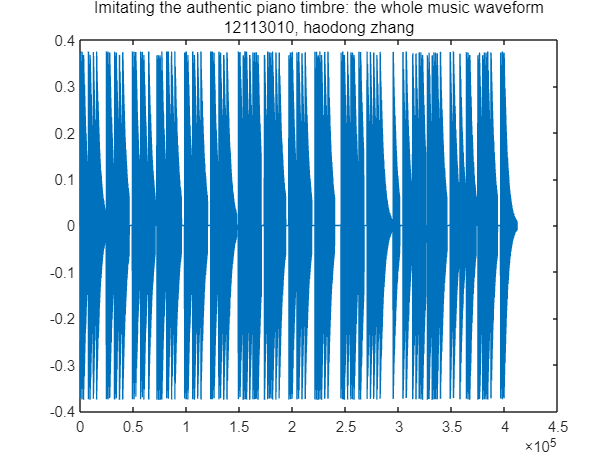

figure;
plot(music)
title(sprintf('Imitating the authentic piano timbre: the whole music waveform\n12113010, haodong zhang'))

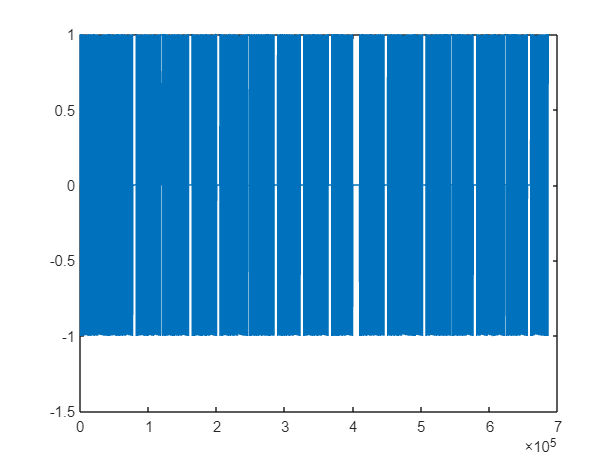

plot(song_tiankong_null);

sound(song_tiankong_null,8192)

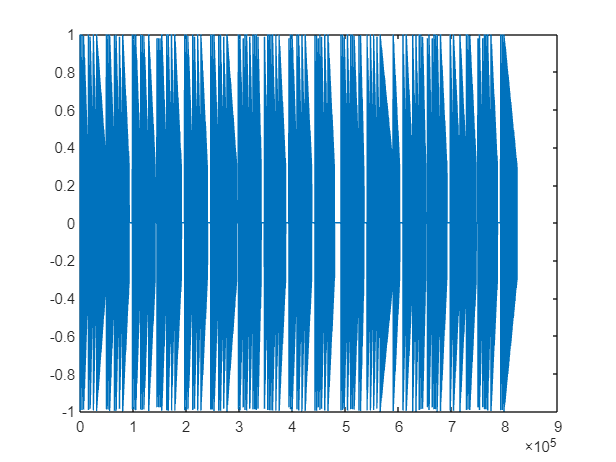

plot(song_tiankong_line);

sound(song_tiankong_line,8192)

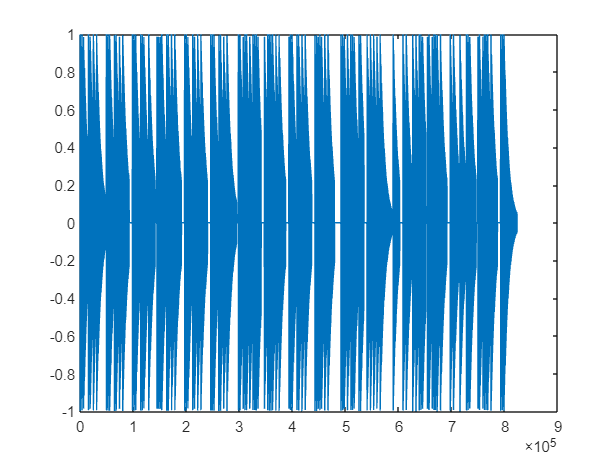

plot(song_tiankong_exp);

sound(song_tiankong_exp,8192)

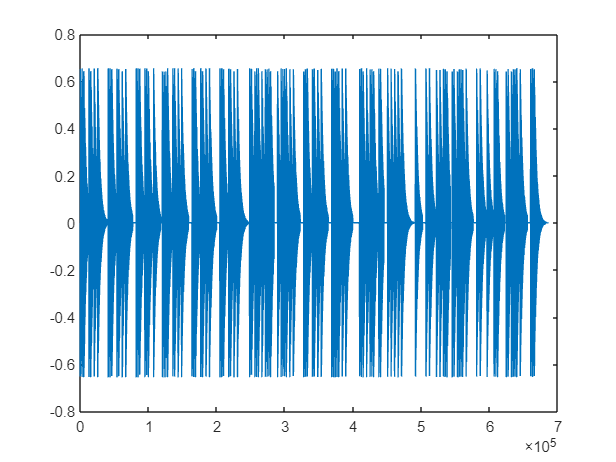

figure;
plot(song_tiankong_exp_2);

sound(song_tiankong_exp_2,8192)

clear sound; 

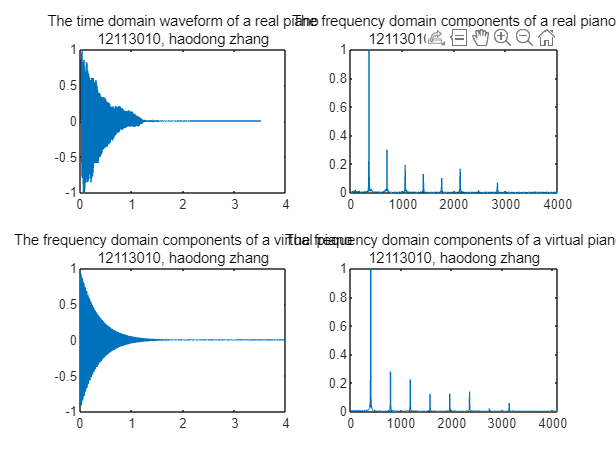

figure;
sample=audioread("4 F.mp3"); 
sample=sample(:,1);
sample=sample/max(sample);
samplet=(1:length(sample))/44100;
sound(sample,44100)
clf;subplot(2,2,1);plot(samplet,sample);
title(sprintf("The time domain waveform of a real piano\n12113010, haodong zhang"));
ylim([-1,1]);
samplel=length(samplet);
samplen=2^nextpow2(samplel);
sampley=fft(sample,samplen);
samplep=abs(sampley/samplel);
samplep=samplep/max(samplep);
samplep=samplep(1:ceil(samplen/2));
samplep(2:end-1)=samplep(2:end-1);
subplot(2,2,2);plot(0:(44100/samplen):(44100/2-44100/samplen),samplep);
title(sprintf("The frequency domain components of a real piano\n12113010, haodong zhang"));
xlim([0,4000]);

fs = 8192;
testt=linspace(0, 4, fs*4);
testf=391.803;
wave=sin(2*pi*testf*testt);
k=[1,0.285,0.222,0.12,0.1246,0.141,0.02,0.059];
for i=2:8
    wave=wave+k(i).*sin(2*pi*testf*i*testt);
end
wave=wave/max(wave);                        
wave=wave.*(testt.^0.01.*exp(-3*testt));   
subplot(2,2,3);plot(testt,wave);ylim([-1,1]);
title(sprintf("The frequency domain components of a virtual piano\n12113010, haodong zhang"));
testl=length(testt);
testn=2^nextpow2(testl);
testy=fft(wave,testn);
testp=abs(testy/testl);
testp=testp/max(testp);
testp=testp(1:ceil(testn/2));
testp(2:end-1)=testp(2:end-1);
subplot(2,2,4);plot(0:(fs/testn):(fs/2-fs/testn),testp);ylim([0,1]);
title(sprintf("The frequency domain components of a virtual piano\n12113010, haodong zhang"));

sound(wave,8192);
